# **DEMO:  **Test the Road profile model

In this example we'll test a **road profile model** that we'll use to stimulate our car dynamics(TRANSVERSE) models.  The road model involves defining a series of "humps" that are repeated along a stretch of road.  Specifically we'll:

- Introduce the parameterized road profile model

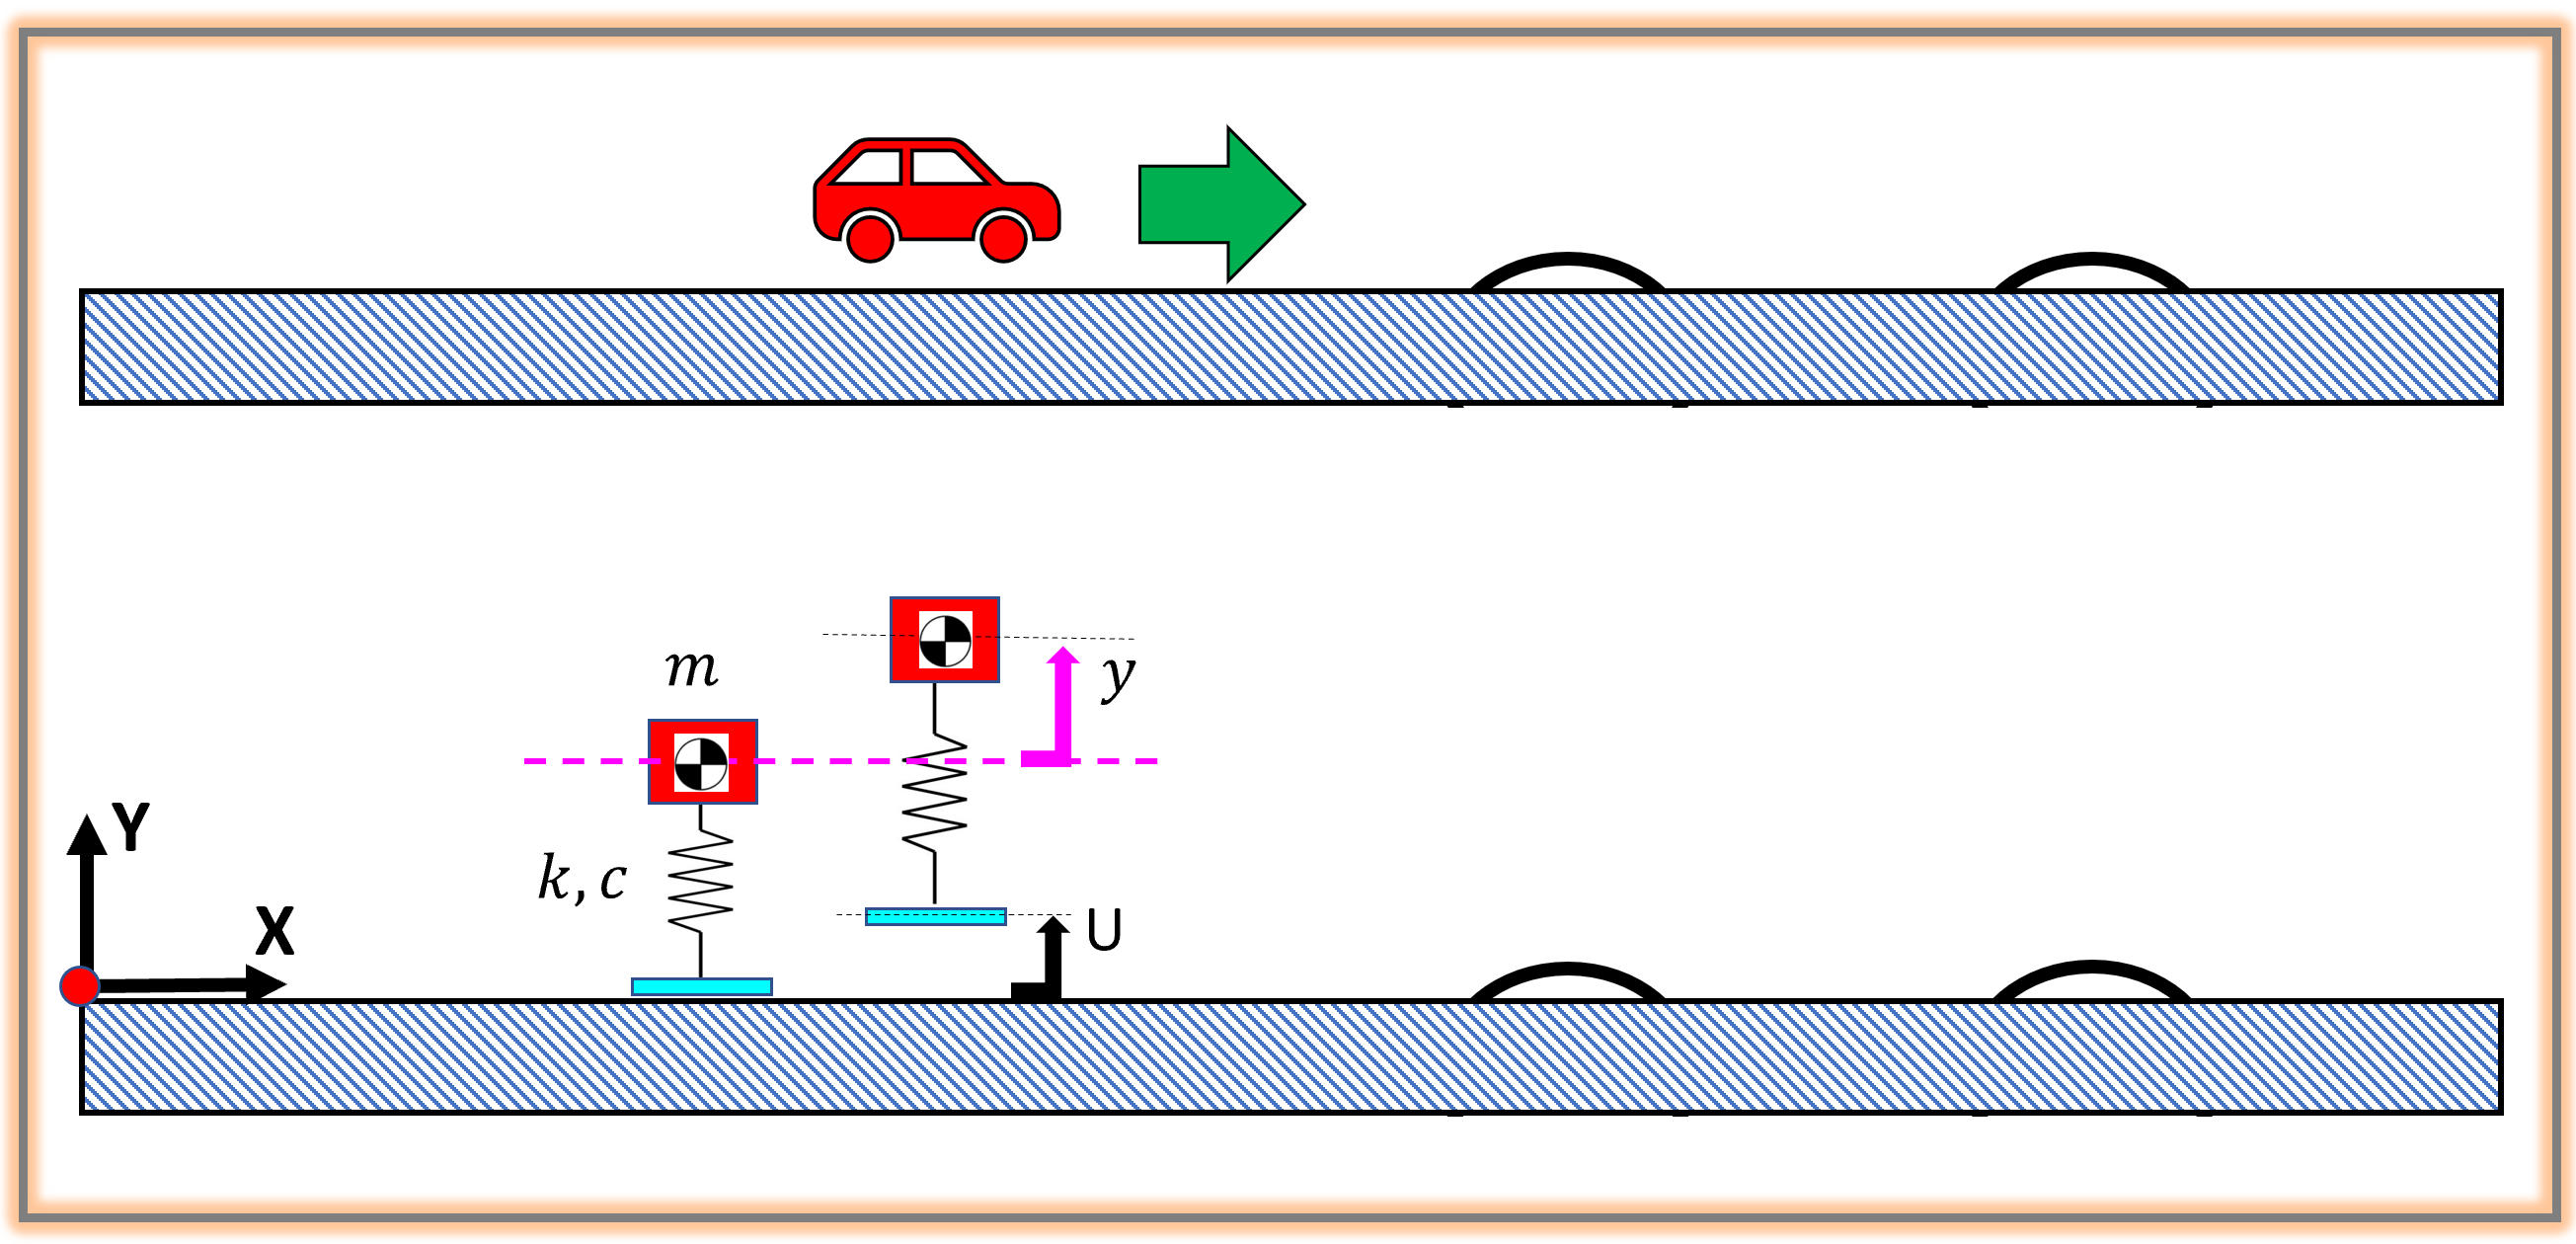

`Bradley Horton : 6-Apr-2026, bhorton@mathworks.com`

## The Road Profile model

Our Road profile model is summarized by the figure below.  Note the 4 parameters for this model:

- `   x_offset :`    (m)  the horizontal distance at which the FIRST hump begins

- `   Lx       :`    (m)  the **width** of the hump

- `   Hy       :`    (m)  the **Height** of the Hump

- `   P        :`    (m)  the spatial Period of the repeating block (ie: the distance between Humps)

The "Hump" portion is just a simple Sine wave of the form:

- 
$$U\left(x\right)\;={\;H}_Y \ldotp \sin \left(\frac{2\ldotp \pi \ldotp x}{\lambda }\right)\;=\;{\;H}_Y \ldotp \sin \left(\frac{2\ldotp \pi \ldotp x}{2\ldotp L_X }\right)\;=\;\;\;H_Y \ldotp \sin \left(\frac{\pi \ldotp x}{L_X }\right)$$


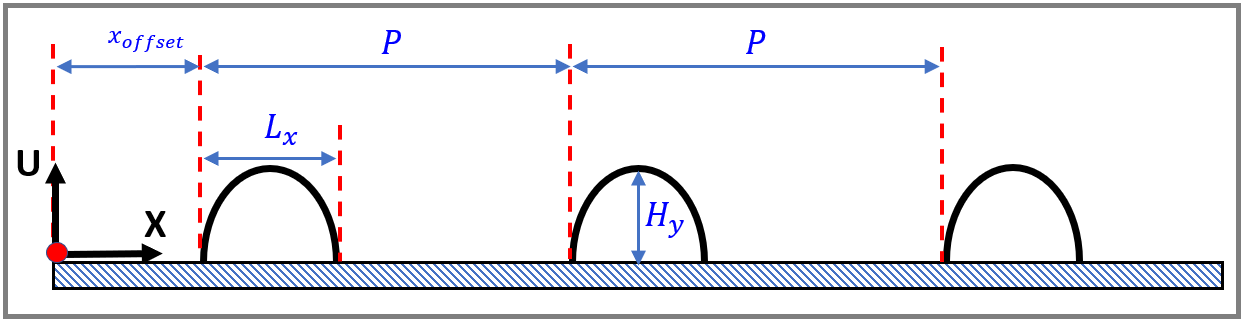

This road model is implemented in 2 files: 

- [`bh_road_profile_half_sine_periodic.mlx`](matlab:  edit bh_road_profile_half_sine_periodic.mlx) : this is a standard MATLAB function and defines the profile shown above

- [`bh_road_hump_A_SYSO.m`](matlab:  edit bh_road_hump_A_SYSO.m) : this is a System object class file.  We'll use this in our Simulink model. This simply uses the `bh_road_profile_half_sine_periodic.mlx `function .... AND it also allows us to "configure" a block for Simulink.  

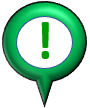**ATTENTION:**

- Also, a useful lookup table ([`bh_speed_vs_distance_explore.xlsx`](matlab:  winopen bh_speed_vs_distance_explore.xlsx)) relating car speed to corresponding distance traveled in 1 millisecond is listed below.

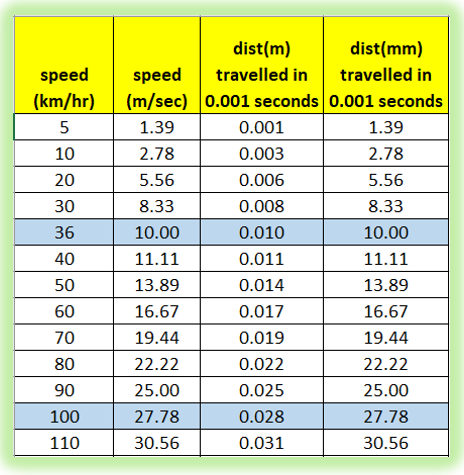

## Test the Road profile model

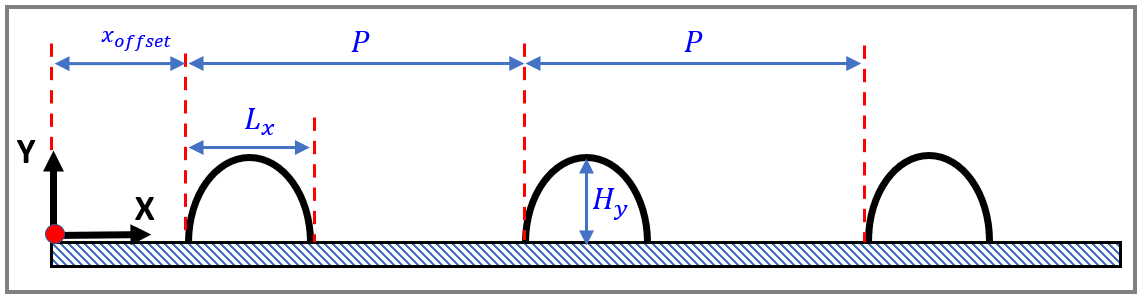

OK:  Let's explore a road profile

the_Hy          = 0.19;
the_Lx          = 0.8;
the_P           = 2.7;
the_x_offset    = 2;
the_NUM_PERIODS = 5;

OBJ = bh_road_hump_A_SYSO("Hy",the_Hy, "Lx",the_Lx, "P",the_P, ...
                          "x_offset",the_x_offset, "NUM_PERIODS",the_NUM_PERIODS);

Plot the road profile in the **spatial domain:**

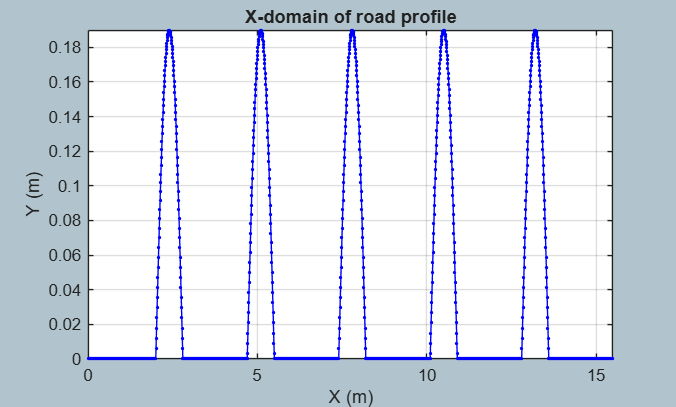

OBJ.plot_X_domain()

axis("tight")

For a constant car speed, plot the road profile in the **time domain:**

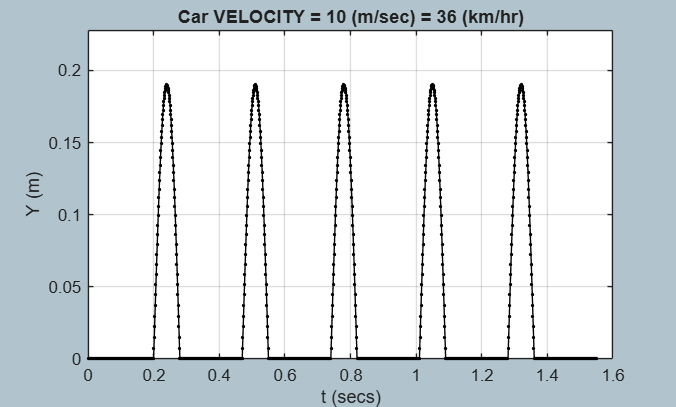

car_speed_mps = 10;  % (m/sec)

OBJ.plot_t_domain(car_speed_mps, "units", "m/s")